# Two-photon microscopy data analysis

This notebook is designed to analyze data obtained from two-photon microscopy, specifically for the Cold Spring Harbor Laboratory (CSHL) Drosophila Neurobiology course.

The analysis will focus on various aspects of the collected data, including visualizing the volumes, registering the volumes, image processing, quantification of neuronal activity, and visualization of results.

The goal is to provide a short introduction to analyzing datasets obtained from two-photon microscopy. 

## Setup libraries and folder locations

Here I load the required libraries, setup the data folders, etc. 

% Set folder names
curr_folder = pwd;
repo_folder = fullfile(curr_folder, '..');
data_folder = fullfile(repo_folder, 'data');

% Dataset name
dataset_name = '20240706a_00004_00001.tif'

dataset_name = '20240706a_00004_00001.tif'


% Load external libraries (that in in toolbox)
addpath(genpath(fullfile(pwd, 'toolbox/')));

## Loading and visualization datasets

In this section, we will load the dataset and visualize the volume as well as the linked metadata acquired during imaging. We will be using the scanimage library to load the tiff.

The below guide assumes that the two-photon microscope you are using saves the data as TIFF files (generally true as this is the default format).

### Load dataset

% Import Tiff Reader
import ScanImageTiffReader.ScanImageTiffReader;

% Setup reader to load dataset
reader = ScanImageTiffReader(fullfile(data_folder, dataset_name));

% Load dataset
volumes = reader.data(); % Load the volumes from the TIFF dataset
metadata = reader.metadata(); % Load metadata


### Visualizing images dataset

Volumes are stored as 3D arrays, i.e. a stack of images (like the ImageJ / Fiji visualization). The first two dimensions are the image resolution, the third dimension is number of such images that are acquired. They are technically not volumes as there is no information about the depth of acqusition for each image.

We can do some exploratory investigation by looking at the dimensions, the number of images in the stack and visualize individual images.

% Learn more about the volumes
disp(['Size of volumes: ', num2str(size(volumes))]);

Size of volumes: 128    128  17000


image_count = size(volumes, 3);
image_selection = image_count/500; % variable for the slider step
disp(['Number of images in volumes: ', num2str(image_count)])

Number of images in volumes: 17000


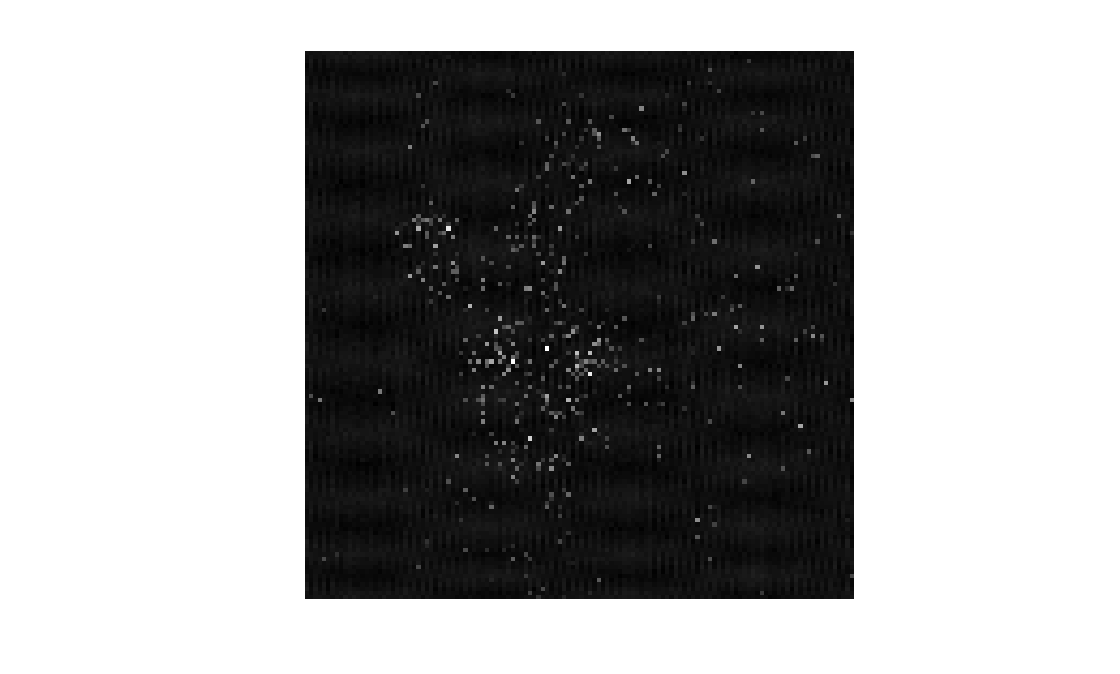

% Show the first image in the stack with automatic grayscale scaling and magnify it (128x128 is too small)
imshow(volumes(:, :, 1), [], "InitialMagnification", "fit"); 

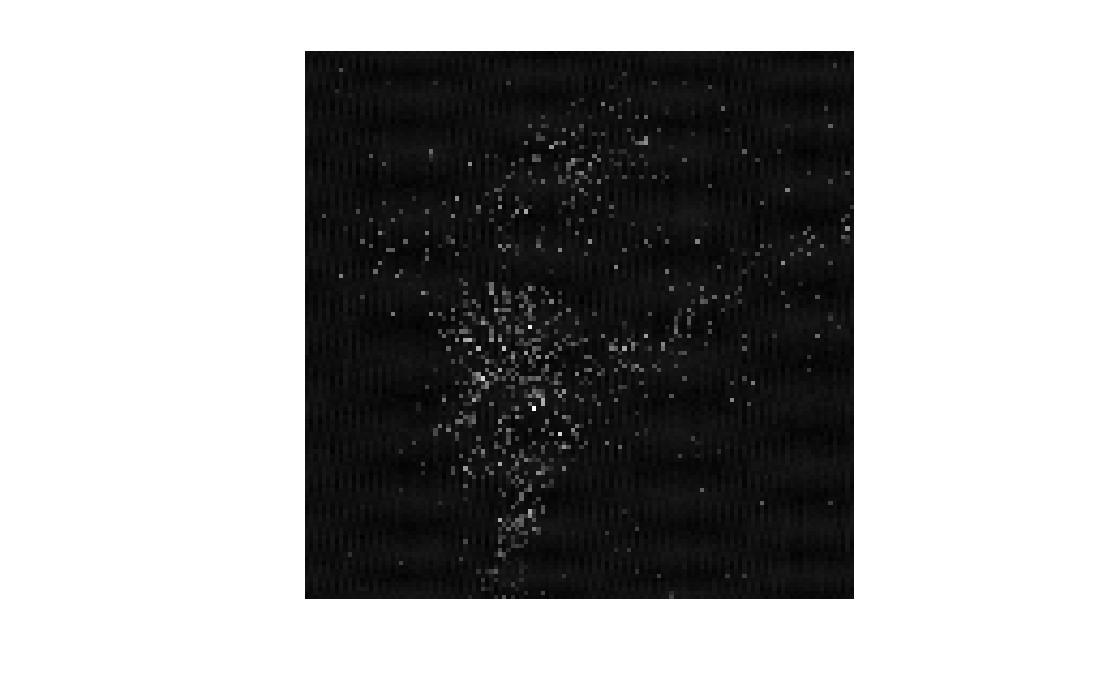

% Display image based on a slide location
curr_ind=18;
imshow(volumes(:, :, curr_ind), [], "InitialMagnification", "fit");

**Task:** Move the slide and visualize how the images look at locations 16, 17 and 33, 34. What do you find?

### Interpretting metadata saved with dataset

The Tiff file essentially gives a stack of images. To make sense of volumes from it, we need to read the metadata that is saved along with the diff file. 

Using the metadata properly is tricky as it needs to be properly formatted as a variable - for now, let us just see the metadata. In addition to looking at the first few lines of the metadata below, double click the variable from the workspace and look at it a bit more.

metadata_lines = splitlines(metadata)

metadata_lines = 472×1 cell array
    {'SI.LINE_FORMAT_VERSION = 1'                                    }
    {'SI.PREMIUM = true'                                             }
    {'SI.TIFF_FORMAT_VERSION = 4'                                    }
    {'SI.VERSION_COMMIT = '2af5d7cfec2f1f15c7a4f5cfcb6b56de9e5d4a1d''}
    {'SI.VERSION_MAJOR = 2021'                                       }
    {'SI.VERSION_MINOR = 1'                                          }
    {'SI.VERSION_UPDATE = 0'                                         }
    {'SI.acqState = 'grab''                                          }
    {'SI.acqsPerLoop = 1'                                            }
    {'SI.errorMsg = '''                                              }
    {'SI.extTrigEnable = false'                                      }
    {'SI.fieldCurvatureRxs = []'                                     }
    {'SI.fieldCurvatureRys = []'                                     }
    {'SI.fieldCurvatureTilt = 0'           

To make sense of the Tiff file, we need to know the number of Z-stacks in each volume, and the number of volumes in our dataset. Additionally, during two-photon imaging flyback frames are sometimes saved as blank frames (the visualized 16, 17, 33, 34). We need to ignore them when processing our dataset. All this data can be found in the metadata.

Before we look into the metadata for this information, let's format the metadata for ease of access.

% Using a custom function to format the metadata
f_meta = formatScanImageTiffMetadata(metadata)

f_meta = struct with fields:
       LINE_FORMAT_VERSION: 1
                   PREMIUM: 1
       TIFF_FORMAT_VERSION: 4
            VERSION_COMMIT: '2af5d7cfec2f1f15c7a4f5cfcb6b56de9e5d4a1d'
             VERSION_MAJOR: 2021
             VERSION_MINOR: 1
            VERSION_UPDATE: 0
                  acqState: 'grab'
               acqsPerLoop: 1
                  errorMsg: ''
             extTrigEnable: 0
         fieldCurvatureRxs: []
         fieldCurvatureRys: []
        fieldCurvatureTilt: 0
         fieldCurvatureTip: 0
          fieldCurvatureZs: []
                    hBeams: [1×1 struct]
            hCameraManager: [1×1 struct]
                 hChannels: [1×1 struct]
       hConfigurationSaver: [1×1 struct]
        hCoordinateSystems: [1×1 struct]
             hCycleManager: [1×1 struct]
                  hDisplay: [1×1 struct]
                    hFastZ: [1×1 struct]
    hIntegrationRoiManager: [1×1 struct]
            hMotionManager: [1×1 struct]
                   hMotors: 

Details about the volume information can be found in hStackManager

% Pull out relevant metadata from the hStackManager
numVolumes = f_meta.hStackManager.numVolumes;
numFrames = f_meta.hStackManager.numFramesPerVolume;
numTotalFrames = f_meta.hStackManager.numFramesPerVolumeWithFlyback;
z_values = f_meta.hStackManager.zs;  

% Print values
disp(['Total volumes: ', num2str(numVolumes)])

Total volumes: 10000


disp(['Number of "Data" frames per volume: ', num2str(numFrames)])

Number of "Data" frames per volume: 15


disp(['Total frames per volume (including "blanks): ', num2str(numTotalFrames)])

Total frames per volume (including "blanks): 17


disp(['Z values for data frames: ', num2str(z_values)])

Z values for data frames: 93   94   95   96   97   98   99  100  101  102  103  104  105  106  107


% Browse hStackManager and see the other metadata stored
f_meta.hStackManager

ans = struct with fields:
                  actualNumSlices: 15
                 actualNumVolumes: 10000
             actualStackZStepSize: 1
                      arbitraryZs: [2×1 double]
           boundedStackDefinition: 'numSlices'
                    centeredStack: 1
        closeShutterBetweenSlices: 0
                           enable: 1
                         errorMsg: ''
                   framesPerSlice: 1
                             name: 'SI StackManager'
                numFastZActuators: 1
               numFramesPerVolume: 15
    numFramesPerVolumeWithFlyback: 17
                        numSlices: 15
                       numVolumes: 10000
                     reserverInfo: ''
                    stackActuator: 'fastZ'
                  stackDefinition: 'uniform'
            stackEndPowerFraction: []
            stackFastWaveformType: 'sawtooth'
                        stackMode: 'fast'
                  stackReturnHome: 1
          stackStartPowerFraction: []
     